# Chap 7 Vision

[llms-with-matlab/examples/DescribeImagesUsingChatGPT.md at main · matlab-deep-learning/llms-with-matlab](https://github.com/matlab-deep-learning/llms-with-matlab/blob/main/examples/DescribeImagesUsingChatGPT.md)

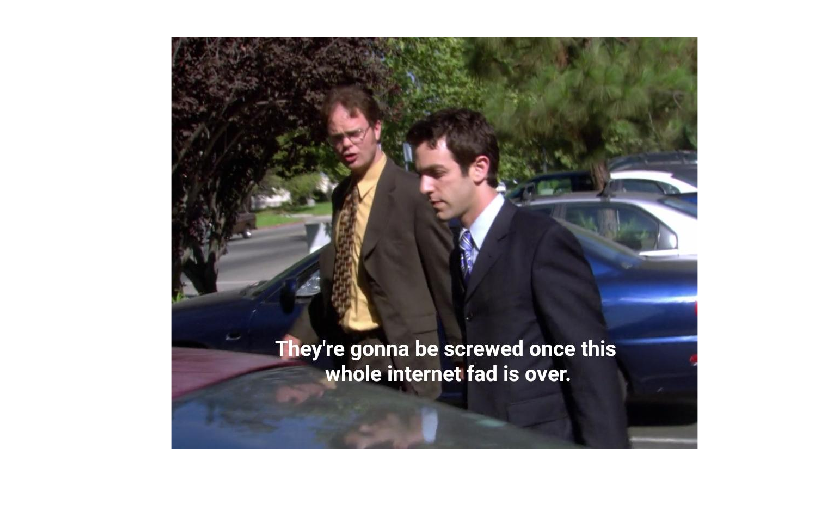

image_url = "https://raw.githubusercontent.com/yanndebray/programming-GPTs/main/img/dwight-internet.jpg";
im = imread(image_url);
imshow(im)

prompt = "What is in the image?";
chat = openAIChat(ModelName="gpt-4o-mini");
messages = messageHistory;
messages = addUserMessageWithImages(messages,prompt, image_url);
generate(chat, messages)

ans = "The image appears to depict two men walking outside, with vehicles parked in the background. One man is wearing a suit and tie, while the other is dressed more casually. The text in the image suggests a conversation about the impact of an "internet fad," indicating a possibly humorous or critical commentary on trends."

prompt = "What is in the image?";
image = "img/parrot8bits_400-400.png";
chatVision(prompt, image)

ans = "The image features a colorful, pixel art representation of a parrot, prominently displaying vibrant shades of blue and orange. The bird's feathers are detailed, showcasing a stylized appearance typical of retro video game art."

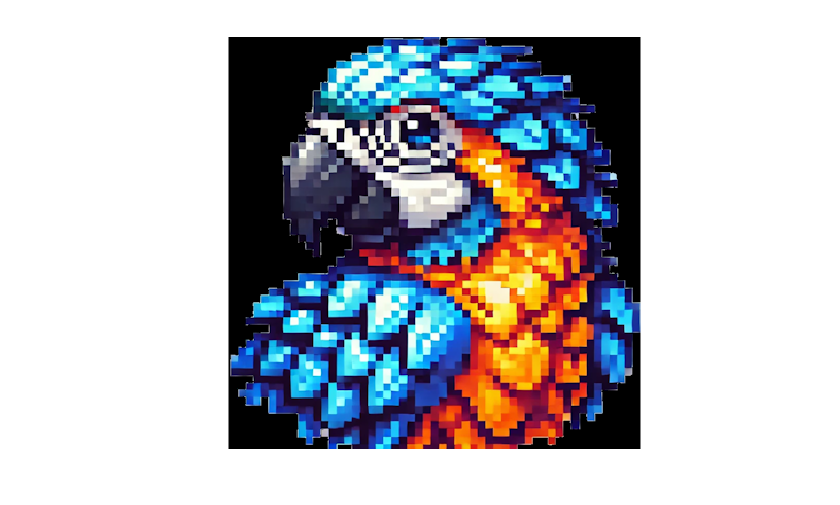

imshow(imread(image))

function response = chatVision(prompt, image)
    chat = openAIChat(ModelName="gpt-4o-mini");
    messages = messageHistory;
    messages = addUserMessageWithImages(messages,prompt, image);
    response = generate(chat, messages);
end